# Matlab introduction exercises :

Based on: 

Beginning Matlab Exercises

R. J. Braun

Department of Mathematical Sciences

University of Delaware

## Advice:

If you feel lost in MatLab, remember you have a good friend called help

## Working with scalars:

Matlab can be used as a calculator. Some of the problems indicate the precedence of arithmetic operations.

1. 3*2^4

v1 = 3*2^4

v1 = 48

2.  (3*2)^4  % parentheses have highest priority

v2 = (3*2)^4 

v2 = 1296

3. 3-2^4

v3 = 3-2^4

v3 = -13

4. 3^4-3

v4 = 3^4-3

v4 = 78

5. 8/2^4

v5 = 8/2^4

v5 = 0.5000

6. 2^4\8    % same as previous! two different divisions, \ and /

v6 = 2^4\8

v6 = 0.5000

7. 8^4/2

v7 = 8^4/2

v7 = 2048

Precedence of arithmetic operations is: (1) parentheses, (2) exponentiation, (3) multiplication and division, and (4) addition and subtraction. Calculations proceed from left to right on the line and equal precedence is settled in this way.

## Starting with Vectors :

It will typically be that our basic unit for computing will be a vector. We need to be able to create and manipulate them.

1. x = [3 4 7 11]  % create a row vector (spaces)

x = [3 4 7 11]

x =      3     4     7    11


2. x = 3:8 % colon generates list; default stride 1

x = 3:8

x =      3     4     5     6     7     8


3. x = 8:-1:0 % start : stride : stop specifies list

x = 8:-1:0

x =      8     7     6     5     4     3     2     1     0


4. xx = [ 8 7 6 5 4 3 2 1 0];  % same as last; semicolon suppresses output

xx = [8 7 6 5 4 3 2 1 0]

xx =      8     7     6     5     4     3     2     1     0


5. xx % display contents

xx

xx =      8     7     6     5     4     3     2     1     0


6. x = linspace(0,1,11) % generate vector automatically

x = linspace(0,1,11)

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


7. x = 0:0.1:1 % same thing

x = 0:0.1:1

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


8. y = linspace(0,1); % note semicolon!

y = linspace(0,1)

y =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


9. length(x)

length(x)

ans = 11

10. length(y)

length(y)

ans = 100

11. size(x)

size(x)

ans =      1    11


12. size(y)

size(y)

ans =      1   100


13. y(3) % access single element

y(3)

ans = 0.0202

14. y(1:12) % access first twelve elements

y(1:12)

ans =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111


15. y([3 6 9 12]) % access values specified in a vector!

y([3 6 9 12])

ans =     0.0202    0.0505    0.0808    0.1111


16. x’ % transpose

x'

ans =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


17. 3*[1 2 5] % factor replicated, multiplies each element

3*[1 2 5]

ans =      3     6    15


Matlab labels the arrays (vectors and matrices) beginning with 1; this will be an important programming in detail on more than one occasion.

## Vectors and matrix arithmetic:

We’ll now explore making matrices and doing arithmetic with them. There are some new arithmetic operations that you did not see before in linear algebra, but they will be useful nonetheless.

1. g = [1; 2; 3; 4]

g = [1; 2; 3; 4]

g =      1
     2
     3
     4


2. g = [1 2 3 4; 5 6 7 8]

g = [1 2 3 4; 5 6 7 8]

g =      1     2     3     4
     5     6     7     8


3. g - 2

g - 2

ans =     -1     0     1     2
     3     4     5     6


4. 2*g-1

2*g-1

ans =      1     3     5     7
     9    11    13    15


5. g = [1 2 3 4; 5 6 7 8; 9 10 11 12]

g = [1 2 3 4; 5 6 7 8; 9 10 11 12]

g =      1     2     3     4
     5     6     7     8
     9    10    11    12


6. h = [1 1 1 1; 2 2 2 2; 3 3 3 3]

h = [1 1 1 1; 2 2 2 2; 3 3 3 3]

h =      1     1     1     1
     2     2     2     2
     3     3     3     3


7. g-h

g-h

ans =      0     1     2     3
     3     4     5     6
     6     7     8     9


8. g*h % What happened?

g.*h

ans =      1     2     3     4
    10    12    14    16
    27    30    33    36


9. h*g

h.*g

ans =      1     2     3     4
    10    12    14    16
    27    30    33    36


10. g.*h % NOT the usual matrix multiplication! Elementwise!

g.*h

ans =      1     2     3     4
    10    12    14    16
    27    30    33    36


11. g./h % elementwise division; denominator below slash

g./h

ans =     1.0000    2.0000    3.0000    4.0000
    2.5000    3.0000    3.5000    4.0000
    3.0000    3.3333    3.6667    4.0000


12. h.\g % Last two same!

h.\g

ans =     1.0000    2.0000    3.0000    4.0000
    2.5000    3.0000    3.5000    4.0000
    3.0000    3.3333    3.6667    4.0000


13. g*h’

g*h'

ans =     10    20    30
    26    52    78
    42    84   126


14. g’*h

g'*h

ans =     38    38    38    38
    44    44    44    44
    50    50    50    50
    56    56    56    56


15. e = [ 1 2 3; 4 5 6; 7 8 0]

e = [ 1 2 3; 4 5 6; 7 8 0]

e =      1     2     3
     4     5     6
     7     8     0


16. f = [9 8 7; 6 5 4; 3 2 1]

f = [9 8 7; 6 5 4; 3 2 1]

f =      9     8     7
     6     5     4
     3     2     1


17. e*f

e*f

ans =     30    24    18
    84    69    54
   111    96    81


18. f*e % Not same!

f*e

ans =     90   114    75
    54    69    48
    18    24    21


19. q = rand(3) % matrix with elements uniformly on [0,1]

q = rand(3)

q =     0.2763    0.9635    0.5216
    0.6223    0.0859    0.0902
    0.5884    0.5005    0.9047


20. A^2 % raise matrix to a power

A = rand(4); A^2

ans =     1.3262    1.4711    0.7264    1.5386
    0.8868    1.3089    0.6458    0.8901
    1.2884    0.9503    0.5761    1.1788
    0.8011    0.6625    0.5289    1.0618


21. A^2 - A*A % verify with definition

A^2 - A*A

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


22. A.^2 % square each element

A.^2

ans =     0.7821    0.3842    0.0385    0.6376
    0.1927    0.0679    0.0923    0.9751
    0.6111    0.1986    0.2336    0.0253
    0.0220    0.7123    0.1141    0.0561


23. A.^2 - A*A % not the same!

A.^2 - A*A

ans =    -0.5440   -1.0869   -0.6879   -0.9010
   -0.6941   -1.2409   -0.5534    0.0850
   -0.6773   -0.7517   -0.3425   -1.1535
   -0.7790    0.0499   -0.4147   -1.0057


## Creating standard arrays:

There are some arrays or matrices that we will be using very often. MatLab has usually shortcurts to produce them.

1. ones(3) % All ones

ones(3)

ans =      1     1     1
     1     1     1
     1     1     1


2. zeros(2,5) % All zeros

zeros(2,5)

ans =      0     0     0     0     0
     0     0     0     0     0


3. size(zeros(2,5))

size(zeros(2,5))

ans =      2     5


4. size(g)

size(g)

ans =      3     4


5. ones(size(g))

ones(size(g))

ans =      1     1     1     1
     1     1     1     1
     1     1     1     1


6. eye(4) % Identity matrix

eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


7. eye(2,4)

eye(2,4)

ans =      1     0     0     0
     0     1     0     0


8. eye(4,2)

eye(4,2)

ans =      1     0
     0     1
     0     0
     0     0


9. rand(3) % Random elements uniformly distributed between 0 and 1

rand(3)

ans =     0.7022    0.9723    0.4019
    0.3755    0.6437    0.6319
    0.9737    0.8601    0.9852


10. b = eye(3)

b = eye(3)

b =      1     0     0
     0     1     0
     0     0     1


11. rand(size(b))

rand(size(b))

ans =     0.5595    0.4840    0.1987
    0.9336    0.6390    0.3954
    0.7203    0.8876    0.9922


12. a = 1:4

a = 1:4

a =      1     2     3     4


13. a = 1:2:9

a = 1:2:9

a =      1     3     5     7     9


14. diag(a)

diag(a)

ans =      1     0     0     0     0
     0     3     0     0     0
     0     0     5     0     0
     0     0     0     7     0
     0     0     0     0     9


15. diag(a,1)

diag(a,1)

ans =      0     1     0     0     0     0
     0     0     3     0     0     0
     0     0     0     5     0     0
     0     0     0     0     7     0
     0     0     0     0     0     9
     0     0     0     0     0     0


16. diag(a,-2)

diag(a,-2)

ans =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     1     0     0     0     0     0     0
     0     3     0     0     0     0     0
     0     0     5     0     0     0     0
     0     0     0     7     0     0     0
     0     0     0     0     9     0     0


17. linspace(1,10,10)

linspace(1, 10, 10)

ans =      1     2     3     4     5     6     7     8     9    10


## Array manipulation

Many times we just want to alterate part of an array or creating a new one from the content of an existing one. MatLab has nice and effective ways to do that

g = [1 2 3 4; 5 6 7 8; 9 10 11 12]

g = [1 2 3 4; 5 6 7 8; 9 10 11 12]

g =      1     2     3     4
     5     6     7     8
     9    10    11    12


2. g(3,2) % single element

g(3,2)

ans = 10

3. g(:,2) % all rows, second column

g(:,2)

ans =      2
     6
    10


4. g(2,:) % second row, all columns

g(2,:)

ans =      5     6     7     8


5. g(1:2,:)

g(1:2,:)

ans =      1     2     3     4
     5     6     7     8


6. g(2,:) = [1 1 1 1] % replace row

 g(2,:) = [1 1 1 1]

g =      1     2     3     4
     1     1     1     1
     9    10    11    12


7. g(:,2) = [2; 2; 2] % replace column

g(:,2) = [2; 2; 2]

g =      1     2     3     4
     1     2     1     1
     9     2    11    12


8. G = [g; 9 10 11 12]

G = [g; 9 10 11 12]

G =      1     2     3     4
     1     2     1     1
     9     2    11    12
     9    10    11    12


9. G = [G [1;2;3;4] ]

G = [G [1;2;3;4] ]

G =      1     2     3     4     1
     1     2     1     1     2
     9     2    11    12     3
     9    10    11    12     4


## Some usefull comands:

1. clc

clc

2. clear g G

clear g G

3. clear all

clear all

## Reserved words:

Matlab has a list of reserved words that has a prescribed value or that corresponds to internal functions.

The following words are already used in Matlab and they must be avoided: for, end, if, while, function, return, elseif, case, otherwise, switch, continue, else, try, catch, global, persistent, break. (You can use similar words by capitalizing one or more letters if your system is case sensitive.) the following variable names are special in Matlab and you should avoid changing them unless you are very careful about what you are doing: ans, beep, pi, eps, inf, NaN, nan, i, j, nargin, nargout, realmin, realmax, bitmax, varargin, vararout.

1. end = 1 % you should get an error

End = 1

End = 1

2. End = 1 % could get error, depending on system

End = 1

End = 1

3. pi = 3 % forgetting thousands of years of progress!

pi = 3

pi = 3

4. pi

pi

pi = 3

5. clear pi

clear pi

6. pi % back to the present!

pi

ans = 3.1416

## Functions:

MatLab has a very big internal library  which offers many implementations of the more required computer sc ience and mathematical solutions. You can use them anytime you want without the need of including them. You can find a list in the help menu. 

1. help elfun % An short list of the most elemental functions

help elfun

  Elementary math functions.
 
  Trigonometric.
    sin         - Sine.
    sind        - Sine of argument in degrees.
    sinh        - Hyperbolic sine.
    asin        - Inverse sine.
    asind       - Inverse sine, result in degrees.
    asinh       - Inverse hyperbolic sine.
    cos         - Cosine.
    cosd        - Cosine of argument in degrees.
    cosh        - Hyperbolic cosine.
    acos        - Inverse cosine.
    acosd       - Inverse cosine, result in degrees.
    acosh       - Inverse hyperbolic cosine.
    tan         - Tangent.
    tand      

 2. Run the next box and observe the results

n = 11;
u = linspace(0,2*pi,n)

u =          0    0.6283    1.2566    1.8850    2.5133    3.1416    3.7699    4.3982    5.0265    5.6549    6.2832


v = cos(u) % all function evaluations done at once!

v =     1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000


You can create new functions, they are (generally) separate files that has to be on the MatLab path in order to be callable. 

3. Take a look on the attatched function 'DummyFunction.m' and execute the next box

a=rand(5);
b=rand(5);
[s,m] = DummyFunction(a,b);

4. Create a function named 'evaluateMyFcn(x)' that given a column vector x, returns the value of the function


$$f(x) = \frac{1 +x^2}{1+abs(x)}$$


for every entry of x. Try to do it in only one line

x = linspace(-10,10,25)';

[x] = evaluateMyFcn(x)

x =     9.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.7298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.4040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.2045         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

## Logical and relational operators:

MatLab is not only a powerfull calculator, but a programming language. In order to control the flux execution of a program we need to evaluate logic conditions.

Relational operators carry out comparisons or tests and the result is to return logical values True (1) or

False (0). The relational operators that are available (and their Matlab form) are: less than (<), less than

or equal to (<=), greater than (<), greater than or equal to (>=), equal to (==), and not equal to (∼=).

Note that == is a test between two quantities, while = assigns a value to a variable. We can use these to

compare scalars and arrays; try out the following.

1. a = 4; b = -1; c = 1;

2. a > b % note that the output is a logical value

3. a < b

4. a >= b

5. mytest = (abs(b) == c) % parentheses optional but clearer

Things get a little more complicated with arrays. Using the g and h behind, try out the following.

g = [1 2 3 4; 5 6 7 8; 9 10 11 12];
h = [3 3 4 4; 5 5 6 6; 7 7 8 8];


3. h >= g

4. g == h % note that the output is a logical value

5. bigger = (g >= h)

6. g(bigger)

7. g([0 0 0 1; 1 1 1 1; 1 1 1 1]) % array argument not logical!

We can string relational operators together and manipulate logical variables using logical operators. They are (Matlab in parentheses): logical AND (&), logical OR (|) and logical NOT (~) (Alt Gr 4) .  The NOT operator just changes the value of the logical variable to the other value. A truth table shows what the AND and OR operators do; it will be given in class. The upshot is that the both parts from an AND operator must be True to return a True; only one of the inputs for the OR operator need be True for it to return True. 

Continuing with the last set of Matlab commands, try these out.

1. h >= g

2. p = ~(h >= g)

3. ~p

4. (g == h) & (g > h)

5. (g == h) | (g > h)

6. g >= h

## **For loop** 

The **for loop** repeats the commands that are inside of it. The basic structure is

for <list-of-values>

    <statements-to-be-done>

end

Use this structure to repeat output, or do calculations

1. % for loop now

x = rand(10,1)

x =     0.1080
    0.4599
    0.4509
    0.5511
    0.8054
    0.7009
    0.8722
    0.0522
    0.2197
    0.4596


for k = 1:5
    x(k)
end

ans = 0.1080

ans = 0.4599

ans = 0.4509

ans = 0.5511

ans = 0.8054

2. % for loop doing a calculation

total = 0;
for k = 1:10
    total = total + x(k);
    fprintf('Total for k=%i is %g',k,total)
end

Total for k=1 is 0.108046Total for k=2 is 0.567922Total for k=3 is 1.0188Total for k=4 is 1.56994Total for k=5 is 2.37535Total for k=6 is 3.0762Total for k=7 is 3.94843Total for k=8 is 4.00063Total for k=9 is 4.22031Total for k=10 is 4.67995

3. sum(x) % built in matlab command sums components of vector

Here the command sum can replace the loop; it adds up the elements of a vector.

## If-else statement

Sometimes we want to compute one set of commands or another depending on the result of a relational test.

There are several forms that this sort of construct can take.

**The simplest is**:

*if <expression>*

*    <commands evaluated if True>*

*end*

An example follows; given a positive number of pens, a cost is computed and displayed.

pens = 8;

if (pens >= 0)
    cost = pens*1.99;
    fprintf('Cost of %i pens is $ %f',pens,cost)
end

Cost of 8 pens is $ 15.920000

**Intermediate**

*if <expression>*

*  <commands evaluated if True>*

*else*

*    <commands evaluated if False>*

*end*

The example now prints a warning for negative numbers of pens. Try to change the value associated to pens and see what happen

pens = -1;

if (pens >= 0)
    cost = pens*1.99;
    fprintf('Cost of %i pens is $ %f',pens,cost)
else
    disp('An invalid number of pens was specified.')
end

An invalid number of pens was specified.


The most general form is:

*if <expression1>*

*        <commands evaluated if expression1 is True>*

*elseif <expression2>*

*        <commands evaluated if expression2 is True>*

*elseif <expression3>*

*        <commands evaluated if expression3 is True>*

*elseif <expression4>*

*        <commands evaluated if expression4 is True>*

*else*

*        <commands evaluated if all other expressions are False>*

*end*

We aren’t limited to 4 expressions here; we could add more. We could use this to price pens according to

quantity, as follows.

sale = false;
pens = 25

pens = 25

if (pens >= 0) && (pens < 20)
    cost = pens;
    sale = true;
elseif (pens >= 20) && (pens < 40)
    cost = pens*0.95;
    sale = true;
elseif (pens >= 40) && (pens <= 100)
    cost = pens*0.90;
    sale = true;
else
    disp('not a valid number of pens')
end

if sale
    fprintf('Cost of %i pens is $ %f',pens,cost)
end

Cost of 25 pens is $ 23.750000

Note that leaving off the last part (else and the related commands following it) will result in no action being taken if none of the previous expressions result in True values

## While operator

Sometimes, we want to repeat commands until a condition is satisfied. If we don’t know how many repetitions are required in advance, a while loop is preferable over a for loop. The general structure is

*while <expression>*

*        <commands>*

*end*

The commands inside the while loop will be repeated as long as the expression returns a value of True, provided that expression returns a scalar. If the expression evaluates to an array, then all of the values that result from it must be True for commands to be evaluated. An example follows; it could be typed into a script file or at the command prompt. In the example, we halve a number until it is so small that the computer can’t detect it when added to 1; the last number before this occurs is called machine epsilon and we’ll talk about it more in class.

num = 0; myeps = 1;
while (1+myeps) > 1
    myeps = myeps/2;
    num = num + 1;
end
num

num = 53

myeps = 2*myeps

myeps = 2.2204e-16

eps % matlab’s preset variable for machine epsilon

ans = 2.2204e-16

The result is that myeps = eps = 2 −52 .

## Plots

1. Observe the output of the next code box:

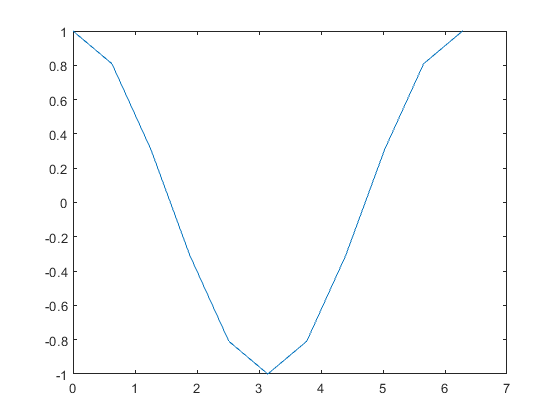

n = 11;
u = linspace(0,2*pi,n);
v = cos(u);
% all function evaluations done at once!
plot(u,v);

2. The last plot had a crude “curve” representing the cosine function; repeat the last example with n=101

to improve the curve.

3. Add these commands to clean up the plot by adding axis labels and a title. The text inside the single

quotes is a string which we intend to be the labels, etc.

xlabel(’u’); ylabel(’v’); title(’v = cos(u)’);

4.  The next box approximates the exponential function by :


$$f\left(x\right)=\frac{1-\frac{3}{5}x+\frac{3}{20}x^2 -\frac{1}{60}x^3 }{1+\frac{2}{5}x+\frac{1}{20}x^2 }$$


Observe what the legend function does

n= 150;
x = linspace(0,1,n);
xsqd = x.^2;
num = 1-(3/5)*x+(3/20)*xsqd -(x/60).*xsqd

num =     1.0000    0.9960    0.9920    0.9880    0.9840    0.9800    0.9761    0.9721    0.9682    0.9643    0.9604    0.9565    0.9526    0.9488    0.9449    0.9411    0.9373    0.9335    0.9297    0.9259    0.9221    0.9184    0.9146    0.9109    0.9072    0.9035    0.8998    0.8961    0.8924    0.8888


den = 1+(2/5)*x+(1/20)*xsqd

den =     1.0000    1.0027    1.0054    1.0081    1.0108    1.0135    1.0162    1.0189    1.0216    1.0243    1.0271    1.0298    1.0325    1.0353    1.0380    1.0408    1.0435    1.0463    1.0491    1.0518    1.0546    1.0574    1.0602    1.0629    1.0657    1.0685    1.0713    1.0741    1.0769    1.0797


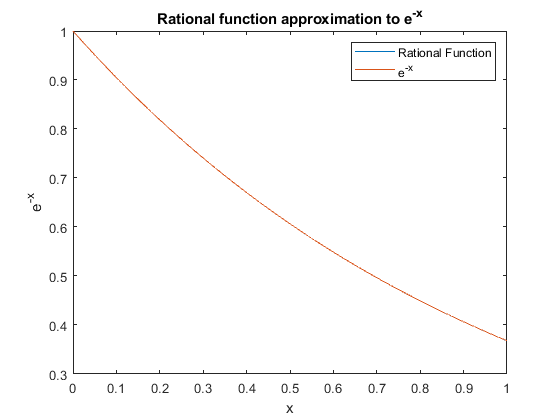

y = num./den;
plot(x,y,x,exp(-x))
xlabel('x');
ylabel('e^{-x}');
title('Rational function approximation to e^{-x}')
legend('Rational Function','e^{-x}')

The commands *figure(), hold on *and *hold off *will allow to create new figures and superpose curves

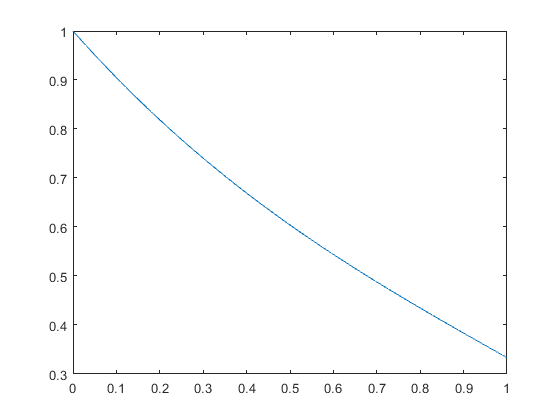

x = linspace(0,1);
y = 1 - x + x.^2/2 - x.^3/6;
exact = exp(-x);
figure % create new figure  window for plotting y
plot(x,y)

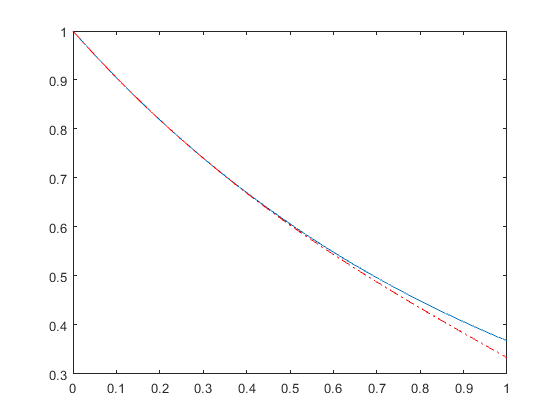

figure % create new figure
plot(x,exact)
hold on
% causes subsequent curves to be added to current figure
plot(x,y,'r-.')
hold off  % returns to normal plotting mode